Létrehozunk egy 3D-s Occupancy map-et 

omap3D = occupancyMap3D

omap3D =   occupancyMap3D with properties:

    ProbabilitySaturation: [1.0000e-03 0.9990]
               Resolution: 1
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000


mapWidth = 50;
mapLength = 50;
numberofObs = 7

numberofObs = 7

Map = zeros(mapLength, mapWidth,5);
MapNumber = 1

MapNumber = 1

size(Map)

ans =     50    50     5


Generáljuk le a Foglaltsági térképet

obsnumber = 1;

while obsnumber <= numberofObs
   width = randi([1 15], 1);
   length = randi([1 15], 1);
   height = randi([1 4], 1);
   xPosition = randi([1 mapWidth - width], 1);
   yPosition = randi([1 mapLength - length], 1);
   
   %A meshgridet a 2D-s nél is tudjuk használni
   [xobstacle, yobstacle, zobstacle] = meshgrid(xPosition:xPosition+width, yPosition:yPosition+length, 1:height);
   xyzObs = [xobstacle(:) yobstacle(:) zobstacle(:)];

   checkIntersection = false;
   for i = 1:size(xyzObs, 1)
       if checkOccupancy(omap3D, xyzObs(i,:)) == 1
           checkIntersection = true;
           break
       end
   end

   if ~checkIntersection
        for i = 1:size(xyzObs,1)
                Map(xyzObs(i,2), xyzObs(i,1), xyzObs(i,3)) = 1;
        end
        setOccupancy(omap3D, xyzObs, 1);
        obsnumber = obsnumber+1;
   end
end

Mivel a drón a talajjal sem ütközhet, amiatt muszáj, hogy azt is elemmé tegyük

[xGRD, yGRD, zGRD] = meshgrid(0:mapWidth, 0:mapLength, 0);
xyzGRD = [xGRD(:) yGRD(:) zGRD(:)];
xyzGRD

xyzGRD =      0     0     0
     0     1     0
     0     2     0
     0     3     0
     0     4     0
     0     5     0
     0     6     0
     0     7     0
     0     8     0
     0     9     0


setOccupancy(omap3D, xyzGRD, 1)


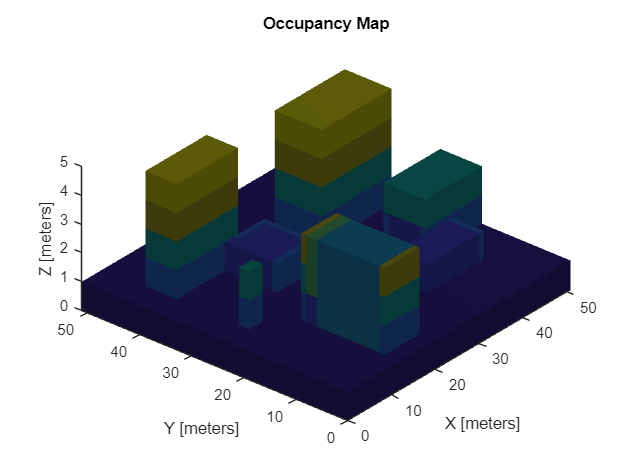

figure("Name","3D Foglaltsági terülel")
show(omap3D)
zlim([0 5])

Map

Map = Map(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     

size(Map)

ans =     50    50     5


save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\occupancy_map_3d" + MapNumber + ".mat", "omap3D");
save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\map_data"+MapNumber+".mat", "Map")
